# Modelagem de um Motor CC - Luis Guilherme

## Boas Práticas

clear all;      %%% limpa as variáveis
close all;      %%% fecha as figuras
clc;            %%% limpa a tela

## Importando os dados

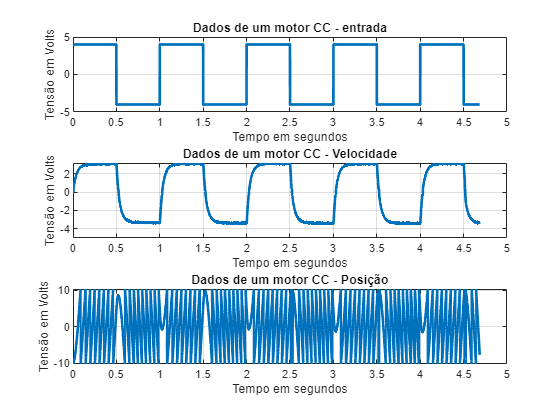

Leitura         %%% importa os dados
T = 1e-3;       %%% Tempo de amostragem
N = length(In); %%% Número de amostras
tempo = linspace(0, N*T,N);

%%% verificando os dados

figure(1)

subplot(3,1,1)  %%% primeiro gráfico em 3 linhas e 1 coluna

plot(tempo,In,'LineWidth',2)
title('Dados de um motor CC - entrada')
xlabel("Tempo em segundos")
ylabel("Tensão em Volts")
grid

subplot(3,1,2)  %%% segundo gráfico em 3 linhas e 1 coluna

plot(tempo,Vel,'LineWidth',2)
title('Dados de um motor CC - Velocidade')
xlabel("Tempo em segundos")
ylabel("Tensão em Volts")
grid

subplot(3,1,3)  %%% terceiro gráfico em 3 linhas e 1 coluna

plot(tempo,Pos,'LineWidth',2)
title('Dados de um motor CC - Posição')
xlabel("Tempo em segundos")
ylabel("Tensão em Volts")
grid

## Estimando um modelo em laplace

%%% Um modelo de primeira ordem que relacione a entrada com a velocidade
Km = 20;             %%% valor inicial do ganho
pm = 10;             %%% valor inicial do polo

%%% Montagem da função de transferência
Gp = tf(Km,[1 pm])  

Gp =
 
    20
  ------
  s + 10
 
Continuous-time transfer function.



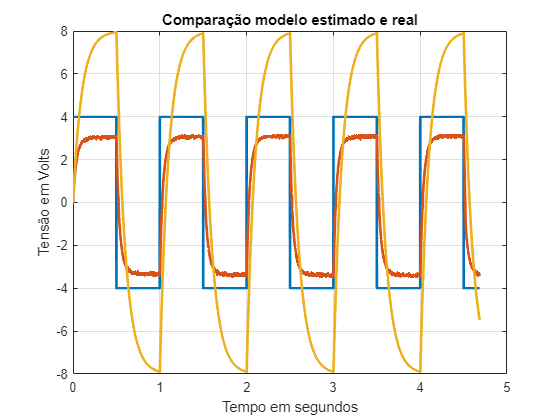


%%% Aplico no modelo a mesma entrada do sistema real
y = lsim(Gp, In, tempo);

figure(2)

%%% Visualizando o resultado

plot(tempo, In, tempo, Vel, tempo, y, "LineWidth",2)
title("Comparação modelo estimado e real")
xlabel("Tempo em segundos")
ylabel("Tensão em Volts")
grid

## Ajustando o modelo com dados

x0 = [1 1];
X = fminsearch(@(x)ErroQuadratico(x,Vel,tempo,In),x0);
Km = X(1);
pm = X(2);

## Comparando o modelo com os dados

%%% Montagem da função de transferência
Gp = tf(Km,[1 pm])

Gp =
 
    22.47
  ---------
  s + 28.09
 
Continuous-time transfer function.



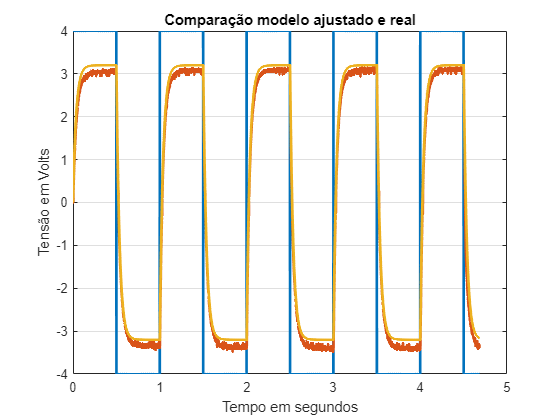


%%% Aplico no modelo a mesma entrada do sistema real
y = lsim(Gp, In, tempo);

figure(3)

%%% Visualizando o resultado

plot(tempo, In, tempo, Vel, tempo, y, "LineWidth",2)
title("Comparação modelo ajustado e real")
xlabel("Tempo em segundos")
ylabel("Tensão em Volts")
grid